# Sensor Calibration: Polynomial Fit

Load the file `sensor_calibration_DATE.mat` from EXP.6 onto MATLAB.

load sensor_calibration_03_05_2024.mat
sensor

sensor =        17092       17540       17620
       24998       24982       29991
       39785       39561       45355
       35432       35464       35880
       36616       31529       30679
       27158       27494       27238
       24838       24918       24630
       22597       22629       22677
       21285       21797       21221
       19508       19732       21733


A more accurate relationship between ADC output voltage, *V*, and ball position, *D*, is

the following second-order polynomial:

*V *= *a ∙ D*^2 + *b ∙ D* + *c*

From the plot of voltage vs. position data, identify a range on the horizontal axis where the

markers seem to follow a parabola (e.g., form holes #4 to #15). In MATLAB, do the following:

1--For each position in the selected range find the mean value of the *N* = 3 measurements taken.

average = trimmean(sensor,50,2); % take a 50% trimmed mean to remove bias from outliers
position = (3:14); % index for range of holes to find polynomial trend
voltage = average(position) % index average array using range of holes

voltage =        39785
       35464
       31529
       27238
       24838
       22629
       21285
       19732
       18068
       16307


2--`Use polyfit(position,voltage,2)` to solve for the parameters *a, b*, and *c* of the

best second-degree polynomial fit to all points in the selected interval.

parameters = polyfit(position,voltage,2); % calculate parameters for 2nd polynomial
% assign the parameters for the data
a = parameters(1)

a = 170.6916

b = parameters(2)

b = -5.1160e+03

c = parameters(3)

c = 5.2972e+04

3--Using the calculated values for parameters *a, b*, and *c* plot the best curve fit inside the

selected range and overlay the markers of the experimental measurements.

Discuss whether the curve passes closely from the markers inside the selected interval.

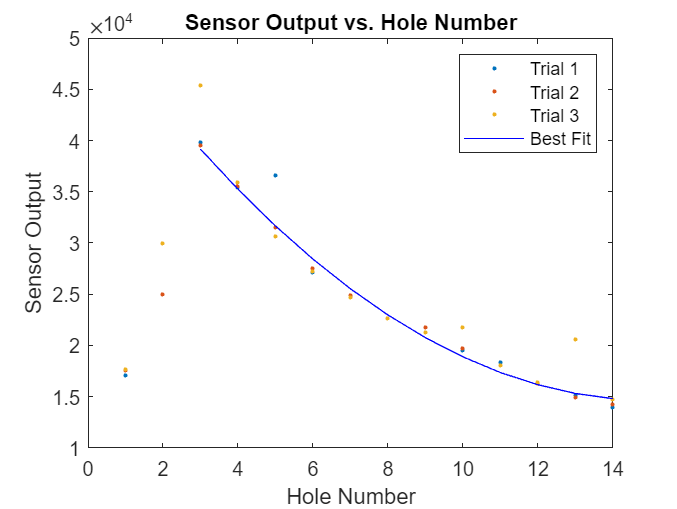

V = a * position.^2 + b * position + c; % calculate curve using calculated parameters

plot(sensor, '.') % overlay experimental measurments
hold on
plot(position, V, 'b') % plot curve
title("Sensor Output vs. Hole Number")
xlabel("Hole Number")
ylabel("Sensor Output")
legend("Trial 1", "Trial 2", "Trial 3", "Best Fit")
hold off

For the purpose of closed-loop ball levitation, the position of the ball corresponding to

the sensor output is needed. To find the parameters *c*, *e*, and* f *of the inverse relationship

*D = c ∙ V*^2 +* e ∙ V + f*

repeat Step 2 with `polyfit(voltage,position,2)`.

parameters = polyfit(voltage,position,2); % calculate parameters for 2nd polynomial
% assign the parameters for the data
format long
c = parameters(1)

c =      1.408663748963732e-08


e = parameters(2)

e =   -0.001169936946725


f = parameters(3)

f =   27.517454984404370
